# 고유 분석의 응용 사례

 이 라이브 스크립트는 표시된 코드와 함께 사용하도록 고안되었습니다. `VIEW` 탭을 선택하고 `Output Inline` 로 전환합니다. 

 이 스크립트의 MATLAB 코딩이 어렵다면 MATLAB의 기본 개념을 배울 수 있는 2시간 `분량의` 무료 온라인 튜토리얼 [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted) 를 참고하세요  

## **진동하는 질량체 (vibrating masses)**

**물리적 시스템과 운동 방정식 **

균일한 장력 $T$와 각 질량체 사이의 수평 거리 $l$을 갖는 끈으로 연결된 $n$ 개 질량체(mass)의 시스템을 생각해 봅시다. 

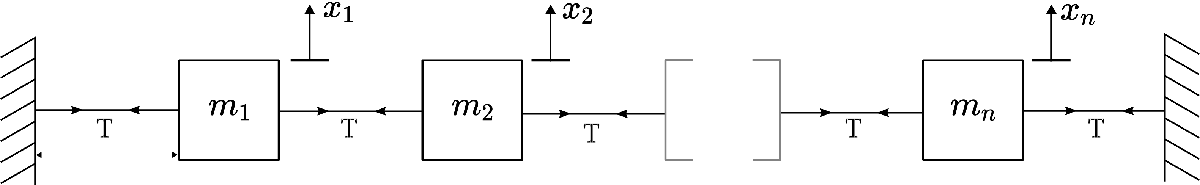

* 등간격으로 연결된 질량체의 시스템 *

각 질량체는 질량 $m_i$와 기준 위치로부터의 수직 변위 $x_i$를 갖습니다.단순화를 위해 질량체는 수직 방향으로만 움직이는 것으로 가정합니다. $i$번째 질량체에 대한 자유물체도를 그려보면 이를 사용하여 운동 방정식을 유도할 수 있습니다. 

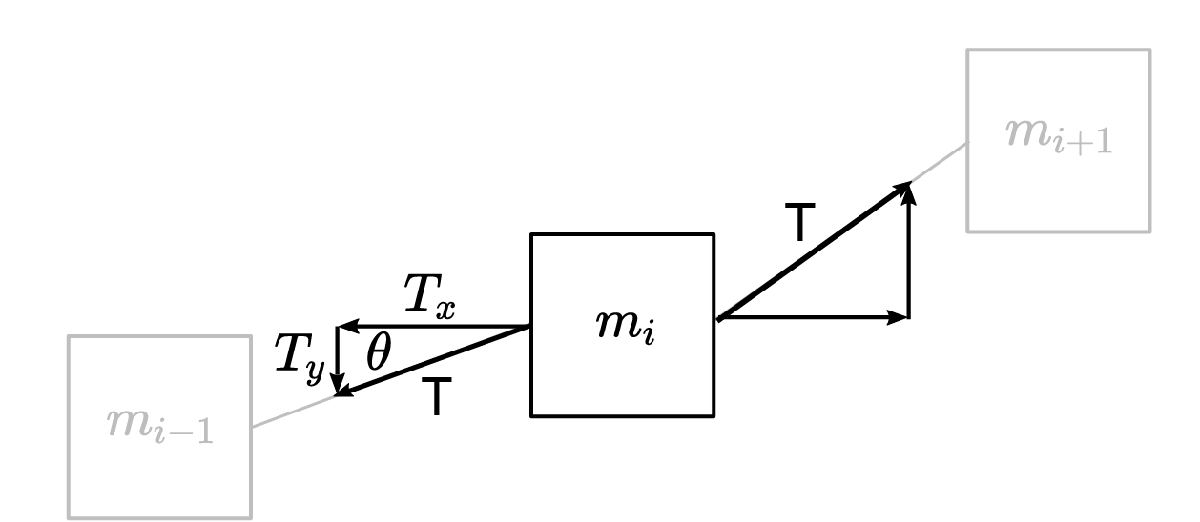

 $i$ 번째*질량체 *의 자유 물체 다이어그램 

각도 $\theta$는 변위와 관련될 수 있습니다. 이 계산에서는 변위가 작아서 질량체 사이의 수평 거리가 $\approx l$ 인 것으로 가정합니다. 


$$\sin \theta = \frac{x_i - x_{i-1}}{l}$$


 $y$ -방향으로 작용하는 힘은 아래와 같습니다.


$$\begin{array}{rl} T_y &= T \sin \theta \\ &= \frac{T}{l} (x_i - x_{i-1}) \end{array}$$


질량체의 반대편에서도 동일한 해석을 수행하면 비슷한 결과가 나옵니다. 뉴턴의 제2법칙을 적용하면 다음과 같은 결과가 나옵니다. 


$$\begin{array}{rl}
m_i \ddot{x}_i &= \frac{T}{l}( - x_i + x_{i-1} )  + \frac{T}{l}(x_{i+1} - x_{i} ) 
\\
m_i \ddot{x}_i &= \frac{T}{l}( x_{i-1} - 2x_i + x_{i+1} )
\end{array}$$


이중 점 표기법은 시간에 대한 2차 도함수를 나타냅니다. $\ddot{x}_i = \frac{d^2 x_i}{dt^2}$. 

단순화를 위해 $m_i = T = l = 1$ 를 가정하고 각 질량체에 대해 


$$\begin{array}{rl}
\ddot{x}_i &=  x_{i-1} - 2x_i + x_{i+1} 
\end{array}$$


을 산출합니다. 첫 번째와 마지막 질량체의 경우 방정식은 동일하지만 한쪽 이웃의 변위가 누락되어 있는 형태입니다. 


$$\begin{array}{rl}
\ddot{x}_1 &=  - 2x_i + x_{i+1} 
\\
\ddot{x}_n &=  x_{n-1} - 2x_n 
\end{array}$$


** 운동 방정식의 행렬 형식 **

이 시스템을 행렬 형식으로 나타내려면 변위 변수의 벡터를 정의합니다: 

$\mathbf{x} = \left( \matrix{ x_1 \cr x_2 \cr \vdots \cr x_n } \right)$. 

이 정의를 사용하면 아래와 같은 형식으로 운동 방정식을 쓸 수 있습니다.


$$\ddot{\mathbf{x}} = \mathbf{A} \mathbf{x}$$


  ** 실습.  **시스템의 질량체 수 `n을` 정의해보세요 (예제의 나머지 부분에서 이 값을 사용합니다). 

n = 4;      % 질량체의 수
 

** 연습**. 정의된 $\mathbf{x}$와 ODE 시스템에 대해: 


$$\begin{array}{rl}
&\ddot{x}_1 =  - 2x_i + x_{i+1} 
\\
&\ddot{x}_i =  x_{i-1} - 2x_i + x_{i+1} 
\\
&\ddot{x}_n =  x_{n-1} - 2x_n 
\end{array}$$


$\ddot{\mathbf{x}} = \mathbf{A} \mathbf{x}$에서 계수 행렬 $\mathbf{A}$의 형태는 어떻게 될까요?   

ShowSolution = true;
if(ShowSolution)
    AForm(n)
end

** 연습 **. MATLAB에서 계수 행렬 $\mathbf{A$을 임의의 질량체 수 $n$에 대한 숫자형 행렬로 정의하세요.

** 힌트**: [`diag`](https://www.mathworks.com/help/matlab/ref/diag.html) 함수를 세 번 사용하여 세 개의 대각 행렬을 만들고 결과를 올바른 계수로 합산합니다. 시스템의 크기는 변수 `n` 에 저장됩니다. 

% 행렬 A를 정의합니다.


** MATLAB의 ODE 시스템에 대한 해법 **

여기서 ODE 시스템 


$$\ddot{\mathbf{x}} = \mathbf{A} \mathbf{x}$$


은 numeric ODE 솔버를 사용하여 해결됩니다. 이 과정에서 ODE는 초기 조건 $\mathbf{x}(0)$ 및 $\dot\mathbf{x}(0)$가 주어지면 해 $\mathbf{x}(t)$를 산출하기 위해 적분됩니다. 

  ** 실습. ** 섹션을 실행하여 솔루션을 확인하세요. ODEStringMasses 함수를 검사하여 ODE 구현이 얼마나 간결한지 확인하십시오. 이와 같은 행렬 표현은 간결한 코드를 작성하는 데 효과적입니다. 

x01 = 0.2;   % 첫 번째 질량체의 초기 변위
tf =10;     % 시뮬레이션 기간
 

x0 = zeros(n,1);
x0(1) = x01;
tlim = [0 tf]; 
[t,x,xdot] = SolveMassesODE(x0,tlim,n);

figure("Position",[100 200 1000 400])
plot(t,x)
xlabel("t")
ylabel("x(t)")
legend("x_{" + strsplit(num2str(1:n)) + "}","Location","EastOutside")

  ** 추가실습**.  

- 위의 질량체 수 `n`를 조정하고 시뮬레이션을 다시 실행합니다. 자연 진동 주파수는 변합니까? 

- 시뮬레이션의 초기 변위와 지속 시간을 조정합니다. $t$가 커지면 어떻게 되나요? 

**움직임을 시각화합니다. **

변위 그래프는 물리적 경험과 연관시키기 어려울 수 있습니다. 움직임을 시각화하려면 이 섹션을 실행하세요. 

x01 = 0.35;   % 첫 번째 질량체의 초기 변위
tf =10;     % 시뮬레이션 기간
Nframes = 110; % 애니메이션 속도를 높이거나 낮추려면 프레임 수를 조정하세요.
 

x0 = zeros(n,1);
x0(1) = x01;
tlim = [0 tf]; 
[t,x,xdot] = SolveMassesODE(x0,tlim,n); 
AnimateODEMasses(t,x,Nframes)

** 고유벡터 및 자연 진동 모드 **

연결된 질량체 시스템의 고유 진동 모드는 계수 행렬 `A` 의 고유벡터를 계산하여 식별할 수 있습니다. 

% 계수 행렬
A = diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1)

** 연습 **.계수 행렬의 고유벡터를 계산하고 시각화해보세요

  ** 실습 **.   MATLAB에서 $\mathbf{A$의 고유 분해를 계산합니다. 출력을 `V` 및 `D` 에 저장합니다. 

  ** 추가실습**. 각 고유벡터는 자연 진동 모드에 따른 질량체의 변위를 나타냅니다. 이 섹션에서는 표시된 질량을 사용하여 고유벡터를 시각화합니다. 모드 인덱스를 조정하여 자연스러운 진동 모드를 확인하세요. 

ModeIndex = 1; % 모드 지수는 <= 질량체 수여야 합니다.
VisualizeMasses(ModeIndex,n) 

 ** 생각해봅시다. . **

- 시뮬레이션 출력을 바탕으로 위에서 생성된 시뮬레이션에서 어떤 모드가 지배적이라고 생각하십니까? 

** ODE 해에 존재하는 모드 계산 **

고유 벡터는 질량체 운동에 대한 대체 기저(alternative basis)를 제공합니다. 고유 벡터 기준으로 솔루션을 표현하여 시뮬레이션에 존재하는 모드를 계산할 수 있습니다. 


$$\mathbf{x} = b_1 \mathbf{v}_1 + b_2 \mathbf{v}_2 + b_3 \mathbf{v}_3 + \ldots + b_n \mathbf{v}_n$$


계수 $\mathbf{b}$는 각 모드의 가중치를 결정합니다. 

행렬 형식에서 이 선형 조합은 다음과 같습니다. 


$$\mathbf{x} = \mathbf{V} \mathbf{b}$$


여기서 $\mathbf{V}$은 고유 분해의 고유 벡터 행렬입니다. 특정 시점 $t$ 에서 모드 계수를 풀기 위해 $\mathbf{b}$ 에 대한 행렬 솔루션을 계산할 수 있습니다. 

** 연습 **. 시뮬레이션의 마지막 시간 단계에서 모드계수 $\mathbf{b}$를 해결합니다. 

** 힌트** : 마지막 시간 단계에서 $\mathbf{x}$ 값에 액세스하려면 다음을 사용하십시오. 

  ** 추가실습**. 이 섹션을 실행하여 솔루션에서 시간에 따른 모드 계수를 플로팅합니다. 모드 계수는 아래의 각 시간 단계에서 계산됩니다. 

figure("Position",[100 200 1000 400]) 
b = zeros(size(x));
[V,~] = eig(A);
for k = 1:length(t)
    b(k,:) = V\x(k,:)'; % 각 시간 단계의 계산 모드 계수
end
plot(t,b) % 여기서 b를 그립니다.
legend("b_{" + strsplit(num2str(1:n)) + "}","Location","EastOutside") % 이것은 플롯에 범례를 추가합니다

 ** 생각해봅시다. . **

- 이 특정 솔루션에 지배적인 모드가 존재하는 것으로 보입니까? 없을 수도 있습니다. 

- 모드마다 진동 주기가 다릅니까? 

** 고유모드 해 **

위 섹션에서는 고유벡터를 사용하여 해를 분석했습니다. 고유벡터 기반을 사용하여 모델의 초기 조건을 구성하는 것도 가능합니다. 이를 위해 시스템의 초기 변위를 자연 모드의 합으로 설정할 수 있습니다. 


$$\mathbf{x}_0 = b_1 \mathbf{v}_1 + b_2 \mathbf{v}_2 + b_3 \mathbf{v}_3 + \ldots + b_n \mathbf{v}_n$$


방정식에 감쇠 항이 없으므로 시스템은 이러한 자연 모드를 사용하여 무한정 계속 진동합니다. 

  ** 실습 **. 새로운 $n$ 요소 모드계수 벡터 `b`를 정의하여 시뮬레이션에 어떤 모드가 나타날지 결정하시오. `b`의 값을 변경하여 다양한 솔루션 모드를 강조할 수 있습니다. 

  ** 실습 **.  계수 벡터 `b`와 고유벡터 행렬 `V`을 기반으로 초기 조건 벡터 `x0`를 계산합니다. 

**움직임 시각화 **

이 섹션을 실행하고 ODE 해를 계산하고 해를 시각화하려면 상자를 선택하십시오. 

tf =20;     % 시뮬레이션 기간
Nframes = 130; % 애니메이션 속도를 높이거나 낮추려면 프레임 수를 조정하세요.
 

tlim = [0 tf]; 
[t,x,xdot] = SolveMassesODE(x0,tlim,n);
AnimateODEMasses(t,x,Nframes)

 ** 생각해봅시다. . **

- 각 고유모드를 개별적으로 인식할 수 있나요? 

- 서로 다른 고유모드에 대해 상대 스케일 인자(즉, 고유벡터 계수 $b_i$ )를 변경하면 어떻게 됩니까? 

- 고유모드 간에 에너지가 전달됩니까? 

- 돌아가서 계수 벡터 $\mathbf{b}$를 변경하여 초기 조건 $\mathbf{x}_0$에 다른 모드가 포함되도록 합니다. 변경 사항이 동적 동작에 생각해봅시다. 됩니까? 

## 마르코프 체인을 사용한 위험 평가

** 배경 **

다섯 가지 위험 범주를 사용하여 고객을 분류한 자동차 보험 회사를 생각해 보세요. 

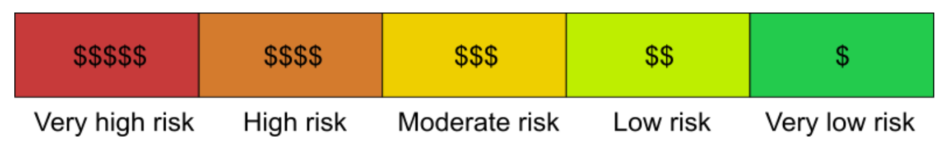

* 위험 카테고리. 고위험 고객은 청구에 대한 지불을 요구할 가능성이 높기 때문에 더 높은 보험료를 지불합니다. *

매년 고객의 위험이 재평가됩니다. 클라이언트는 기록에 따라 카테고리 간에 이동됩니다. 예를 들어, 

- 사고가 발생하면 고객은 더 높은 위험 범주로 이동하게 됩니다. 

- 사고가 없으면 고객은 더 낮은 위험 범주로 이동될 수 있습니다. 

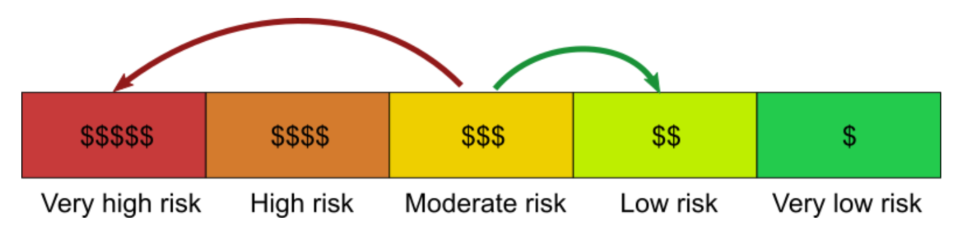

* 카테고리 간 클라이언트 전환이 두 가지 가능합니다. *

마르코프 체인은 과거에 클라이언트가 카테고리 간에 이동한 방식에 대한 기록을 기반으로 클라이언트 풀이 어떻게 변경되는지 모델링하는 데 사용할 수 있습니다. 클라이언트 내역은 클라이언트가 다른 카테고리로 이동하거나 동일한 카테고리에 머무를 확률(1년 이상)로 표시됩니다. 

이 모델의 목표는 다양한 위험 범주의 고객 분포가 향후 어떻게 변할지 결정하는 것입니다. 

** 전환 **

각 범주의 클라이언트 비율을 


$$\mathbf{r} = \left( \matrix{ r_1 \cr r_2 \cr r_3 \cr r_4 \cr r_5 } \right)$$


로 모델링합니다. 각 변수 $r_i$는 각 위험 범주의 클라이언트 비율을 나타냅니다(모든 클라이언트에 대해 $= \sum_i r_i = 1$). 가장 낮은 위험은 $r_5$ 로 표시되고 가장 높은 위험은 $r_1$로 표시됩니다. 매년 고객은 다른 카테고리로 이동하거나 동일한 카테고리에 남을 가능성이 있습니다. 

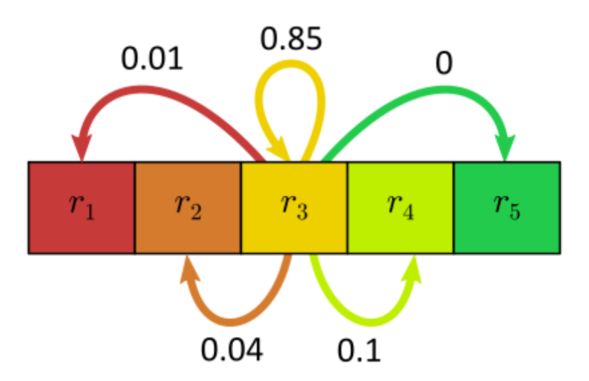

 $r_3$* 고객 전환 가능성. 대다수(85%)가 매년 *$r_3$ *에 남아 있습니다. 클라이언트는 먼저 저위험 범주( *$r_4$* )를 통과해야 하므로 *$r_5$* 로 이동되지 않습니다. *

 $r_3$에서 전체 전환 확률은 1과 같습니다. 이러한 전환은 확률의 한 세트일 뿐입니다. 실제로 각 범주마다 한 세트씩 총 5개의 전환 세트가 있습니다. 

** 전이 행렬 (Transition matrix)**

*전이 행렬 *$\mathbf{P}$는 고객이 매년 5개 카테고리 모두에서 어떻게 이동하는지 모델링합니다. 1년 후 클라이언트의 새로운 분류를 찾으려면 전이 행렬에 현재 상태 벡터 $\mathbf{r}$ : 


$$\mathbf{r}_{new} = \mathbf{P} \mathbf{r}$$


를 곱하십시오. 전이 행렬은 마르코프 체인 모델의 핵심입니다. $\mathbf{P}$의 형식은 

P = sym("p",[5 5])
  

입니다. 각 열은 한 위험 그룹에서 다른 위험 그룹으로 전환될 확률을 결정합니다. 예를 들어, 세 번째 열은 $r_3$ 클라이언트 클래스 외부로의 전환 가능성을 결정합니다. 

- $p_{1,3}$ = $r_3 \rightarrow r_1$ 전환 확률 

- $p_{2,3}$ = $r_3 \rightarrow r_2$ 전환 확률 

- $p_{3,3}$ = $r_3 \rightarrow r_3$ 전환 확률 (동일 카테고리에 유지) 

- $p_{4,3}$ = $r_3 \rightarrow r_4$ 전환 활률 

- $p_{5,3}$ = $r_5 \rightarrow r_4$ 전환 확률 

이와 같이 작동하는 이유는 행렬-벡터 곱셈 $\mathbf{r}_{new} = \mathbf{P} \mathbf{r}$이 다음을 산출하기 때문입니다. 

r = sym("r",[5,1]);
rnew = P*r 

이 결과에서 첫 번째 행은 확률 $p_{1,i}$( $r_i$에서 $r_1$로 이동할 확률)및 $r_i$($i^{th}$ 범주의 현재 클라이언트 비율) 의 곱을 합산합니다. 그 합계는 $r_1$ 범주에서 업데이트된 클라이언트 비율을 산출합니다. 다른 행도 마찬가지로 해석할 수 있습니다. 

** 전이 행렬 구성 **

 $r_3$ 그룹에 대해 위에 표시된 특정 전환을 구현하려면 전환 값을 전이 행렬 $\mathbf{P}$의 세 번째 열에 넣습니다. 

 $r_3$* 고객이 1년에 걸쳐 특정 카테고리로 이동할 가능성. *

P(:,3) = [0.01 0.04 0.85 0.1 0]
  

일반적으로 전환 확률은 과거 데이터로부터 추정됩니다. 유사한 추세가 미래에도 계속된다면 이러한 전환을 통해 고객이 미래에 위험 범주를 어떻게 변경할지 예측할 수 있습니다. 

  ** 실습. ** 아래 이미지에 표시된 전환을 사용하여 `P` 매트릭스의 $r_1$에서 전환을 설정합니다. 

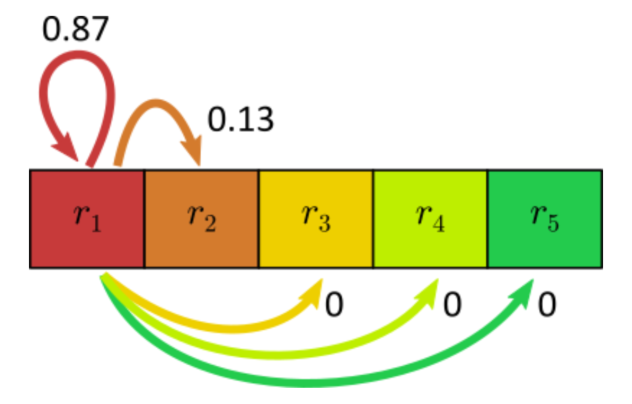

 $r_1$* 고객에 대한 가능성. 이 고객들은 초 고위험범주에서 고위험 범주로만 이동 가능합니다. *

** 힌트 ** : `P(:,i) = [values]` 를 사용하여 행렬의 첫 번째 열을 설정합니다. " `:` " 연산자는 모든 행을 선택합니다. 인덱스 `i`는 열 인덱스를 결정합니다. 

% 여기에 P의 첫 번째 열을 설정하는 코드를 작성하세요.


나머지 전환은 아래와 같이 채워져 있습니다. 

P = [0.87 0.05 0.01 0.01 0.01;
     0.13 0.83 0.04 0.02 0.01;
     0.00 0.12 0.85 0.05 0.02;
     0.00 0.00 0.10 0.90 0.03;
     0.00 0.00 0.00 0.02 0.93]

  ** 시도해 보세요. ** digraph는 전이 행렬을 시각화할 수 있습니다. 이 섹션을 실행하여 digraph를 생성하세요. 

 
figure("position",[1 1 700 650])
G = digraph(P',["r_1","r_2","r_3","r_4","r_5"]);
plot(G,"linewidth",10*sqrt(G.Edges.Weight))

 ** 생각해봅시다.  **

- 어떤 전환의 확률이 가장 높습니까? 

- 이러한 높은 확률의 전환은 전이 행렬에서 어디에 표시됩니까? 

** 전이 행렬 적용 **

처음에 클라이언트가 모든 범주에 균등하게 분포되어 있다고 가정합니다. 

  ** 실습. ** 이 상황을 나타내는 열 벡터 $\mathbf{r}$를 정의합니다( $\sum_i r_i = 1$가 있어야 함). 

  ** 실습. ** 1년 후 새로운 고객 분류는 어떻게 됩니까? 행렬 곱셈을 사용하세요. 

전이 행렬을 반복 적용하여 장기간 후에 고객의 위험 범주 분포를 산출합니다. 

  ** 실습. ** 10년 후 고객의 위험 분포는 어떻게 될까요? 

  ** 실습. ** 100년 후 고객의 위험 분포는 어떻게 될까요? 

 ** 생각해봅시다.  **

- 어떤 카테고리가 가장 큰 고객 점유율을 차지하게 됩니까? 점유율이 가장 작은 것은 어느 것입니까? 

- 비즈니스 관점에서 이러한 장기적인 고객 분산이 바람직한가요? 

- 다른 초기 클라이언트 세트인 $\mathbf{r}$ 로 시작해 보십시오. 이것이 장기 분포에 어떤 영향을 미칩니까? 

** 고유 분석 **

고유값과 고유벡터 측면에서 마르코프 체인의 장기적인 동작을 계산하고 이해할 수 있습니다. 결함이 없는 정사각 행렬은 아래와 같이 고유 분해를 계산하여 대각화할 수 있다는 점을 기억하세요. 

$\mathbf{P} =\mathbf{V \Lambda V}^{-1} $.

이는 1년 후 업데이트의 경우 아래와 같은 상태가 됨을 의미합니다.

$\mathbf{r}_{(1)} = \mathbf{V \Lambda V}^{-1} \mathbf{r}$.

 $n$ 년 후의 상태 분포를 계산하려면 전이 행렬을 $n$ 번 곱하십시오: 


$$\begin{array} {rl}
\mathbf{r}_{(n)} &= ( \mathbf{V \Lambda V}^{-1} )^n\mathbf{r}
\\
  &= (\mathbf{V \Lambda V}^{-1} )(\mathbf{V \Lambda V}^{-1} )\ldots (\mathbf{V \Lambda V}^{-1} )\mathbf{r}
\\
  &= \mathbf{V \Lambda}^n \mathbf {V}^{-1}  \mathbf{r}
\end{array}$$


** 연습 **. $\mathbf{P}$의 고유 분해를 계산하고 출력을 `V` 및 `D`에 저장합니다. 이 매트릭스를 사용하여 100년 후 위험 분포 $\mathbf{r}$를 평가하십시오. 

 % 클라이언트 초기 분배: 각 카테고리에서 20%
 r = [0.2 0.2 0.2 0.2 0.2]'
% 여기서 r(100)을 계산하세요.



** 극한 동작 **

 $\mathbf{\Lambda}$ 에 포함된 고유값을 조사하면 Markov 체인 모델의 극한 동작을 더 직접적으로 이해할 수 있습니다. 전이 행렬의 고유값에는 $\lambda \leq1$ 속성이 있음을 알 수 있습니다. 이 모델의 경우에는 다음이 적용됩니다. 

[~,D] = eig(P) 

이 속성을 사용하면 다음을 표시할 수 있습니다. 


$$\lim_{n\rightarrow \infty} \mathbf{\Lambda}^n = 
\left(\begin{array}{ccccc}
0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0\\
0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0
\end{array}\right)$$


  ** 실습. ** 행렬 $\mathbf{P}_\infty$를 

$\mathbf{P}_\infty =   \lim_{n\rightarrow \infty} \mathbf{V \Lambda}^n \mathbf {V}^{-1}$로 계산하여 시스템의 $n \to \infty$로 제한 동작을 계산합니다. 


$$\begin{array} {rl}
\mathbf{r}_{(n)} = \mathbf{P}^{n}  \mathbf{r}
\end{array}$$
    

결과를 `Pinf` 에 저장합니다. 

  ** 실습. ** 극한 분포를 계산합니다. 


$$\begin{array} {rl}
\mathbf{r}_{(\infty)} = \mathbf{P}^{\infty}  \mathbf{r}
\end{array}$$
    

결과를 `rinf` 에 저장합니다. 

rinf = [];

이 섹션을 실행하면 [`bar`](https://www.mathworks.com/help/matlab/ref/bar.html) 함수를 사용하여 한계 분포를 막대 그래프로 그릴 수 있습니다. 

 
figure("position",[1 1 500 300])
bar([r,rinf])
set(gca,"xticklabel","r_" + strsplit(num2str(1:5)))
ylabel("Fraction of clients")
xlabel("Risk category")
title("$r_\infty$","Interpreter","latex")
legend("r_0","r_\infty")

 ** 생각해봅시다.  **

- 시작 분포 $\mathbf{r}_0$와 극한 분포 사이의 관계는 무엇입니까? $\mathbf{P}_{\infty}$은 이 관계를 정의합니다. 

-  $\mathbf{r}_\infty$의 비즈니스 의미는 무엇입니까? 

Supporting functions for the connected masses application

function [t,x,xdot] = SolveMassesODE(x0,tlim,n)
% 이 함수는 n개 질량체에 대한 상미분방정식(ODE)를 푼다.
    xdot0 = zeros(n,1);
    y0 = [xdot0;x0];
    
    A = diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1);
    odeFunc = @(t,y)ODEStringMasses(t,y,A,n);
    [t,y] = ode45(odeFunc,tlim,y0);
    
    xdot = y(:,1:n);
    x = y(:,n+1:2*n);
end

function [dydt] = ODEStringMasses(t,y,A,n)
% 2차 시스템은 1차
% 방정식 시스템으로 축소되었습니다. 변수 y =[u;x] 여기서 u = x_dot입니다.
    u = y(1:n);
    x = y(n+1:2*n);
    x_dot = u;
    u_dot = A*x;
    dydt = [u_dot;x_dot];    
end

function AForm(n)
% 이는 삼중대각 행렬의 올바른 형식을 계산합니다.
    A = sym(diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1))
end

function AnimateODEMasses(tin,xin,Nframes) 
% 이 함수는 ODE 결과를 플로팅합니다. 

    Nmass = size(xin,2); % 질량체의 수
    t = linspace(tin(1),tin(end),Nframes);
    x = interp1(tin,xin,t);
    
    % 그래프 모양을 결정하는 옵션
    colors = lines(Nmass); 
    w = 0.6; % 질량체 폭
    spacing = 1 + w;
    umax = spacing*(Nmass+1) - w ;
    xub = max(abs(x),[],"all")*2;
    h = w*(1200/325)*(2*xub/umax); % 질량체의 높이
 
    % 반복하여 애니메이션 생성
    f = figure("Visible","On");    
    set(gcf,'position',[100 200 1200 800])   
    for j = 1:numel(t)
       
        subplot(2,1,1) % 이는 대중을 보여준다.
        cla
        hold on
        for k = 1:Nmass
            % 질량체 플롯
            umk = spacing*k -w;
            xm = x(j,k);
            rectangle("Position",[umk x(j,k)-h/2 w h],"FaceColor",colors(k,:))
            text(umk + w/2, xm,"m_{" + num2str(k) + "}","HorizontalAlignment",...
                "center","color","w","fontsize",10)
            % 문자열 플롯
            if(k == 1)
                plot([umk-spacing+w, umk],[0,x(j,k)],SeriesIndex="none")
            else
                plot([umk-spacing+w, umk],[x(j,k-1),x(j,k)],SeriesIndex="none")
            end
        end
        % 마지막 문자열
        umk = umax;
        plot([umk-spacing+w, umax],[x(j,k),0],SeriesIndex="none")

        hold off
        axis([0 umax -xub xub])
        ylabel("x")
        xlabel("reference axis")
    
        subplot(2,1,2) % 움직이는 마커가 있는 위치 플롯을 보여줍니다.
        cla
        hold on
        plot(t,x)
        for k = 1:Nmass
            plot(t(j),x(j,k),"o","SeriesIndex","none","MarkerFaceColor",colors(k,:))
        end 
        xlabel("t [s]")
        ylabel("x(t) ")
        hold off
        box off
        drawnow
    end
    close(f);
end

function VisualizeMasses(ModeIndex,n)
% 이 함수는 x에 정의된 위치로 질량체를 시각화합니다.

    % 계수 행렬
    A = diag(ones(n-1,1),-1) - 2*diag(ones(n,1)) + diag(ones(n-1,1),1);
    [V,~] = eig(A);
    x = V(:,ModeIndex);

    Nmass = length(x); % 질량체의 수
    % 그래프 모양을 결정하는 옵션
    colors = lines(Nmass); 
    w = 0.6; % 질량체 폭
    spacing = 1 + w;
    umax = spacing*(Nmass+1) - w ;
    
    xub = max(abs(x),[],"all")*2;
    h = w*(1200/325)*(2*xub/umax); % 질량체의 높이
 
    % 반복하여 애니메이션 생성
    figure;
    set(gcf,'position',[100 200 1200 400])   
    hold on
    for k = 1:Nmass
        % 질량체 플롯
        umk = spacing*k -w;
        xm = x(k);
        rectangle("Position",[umk x(k)-h/2 w h],"FaceColor",colors(k,:))
        text(umk + w/2, xm,"m_{" + num2str(k) + "}","HorizontalAlignment",...
            "center","color","w","fontsize",10)
        % 문자열 플롯
        if(k == 1)
            plot([umk-spacing+w,umk],[0,x(k)],SeriesIndex="none")
        else
            plot([umk-spacing+w,umk],[x(k-1),x(k)],SeriesIndex="none")
        end
    end
    % 마지막 문자열
    umk = umax;
    plot([umk-spacing+w,umax],[x(k),0],SeriesIndex="none")

    hold off
    axis([0 umax -xub xub])
    ylabel("x")
    xlabel("reference axis")
end


Suppress unused suggestions

%#ok<*INUSL> 
%#ok<*NASGU> 
%#ok<*NOPRT>
%#ok<*UNRCH> 
%#ok<*DEFNU> 
%#ok<*ASGLU> 